clc; clear all; close all;

% PID -> LQG

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


A = [0 1; -1 -2]; 
B=[0 1]'; 
C=[1 0]; 
D = [0]

D = 0


P2 = tf(ss(A,B,C,D))

P2 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


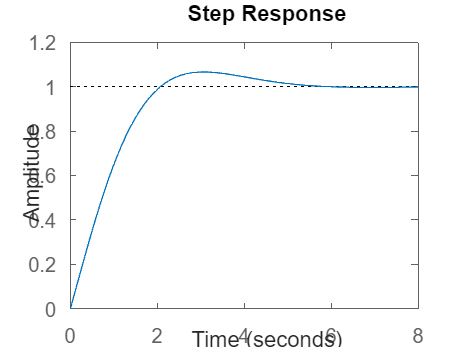

C2=pidtune(P2,'PID');
PCL2=feedback(P2*C2,1);
step(PCL2)


P1 = 1/(s+3);
PCL_a = ss(PCL2)

PCL_a =
 
  A = 
           x1      x2      x3
   x1    -2.7  -1.523  -0.727
   x2       2       0       0
   x3       0       1       0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
           x1      x2      x3
   y1  0.3498  0.5114  0.3635
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


GOL1 = [1/(s+3);1]*PCL_a

GOL1 =
 
  A = 
           x1      x2      x3      x4
   x1      -3  0.3498  0.5114  0.3635
   x2       0    -2.7  -1.523  -0.727
   x3       0       2       0       0
   x4       0       0       1       0
 
  B = 
       u1
   x1   0
   x2   2
   x3   0
   x4   0
 
  C = 
           x1      x2      x3      x4
   y1       1       0       0       0
   y2       0  0.3498  0.5114  0.3635
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



A1=GOL1.A

A1 =    -3.0000    0.3498    0.5114    0.3635
         0   -2.6997   -1.5228   -0.7270
         0    2.0000         0         0
         0         0    1.0000         0


B1=GOL1.B

B1 =      0
     2
     0
     0


C1=GOL1.C

C1 =     1.0000         0         0         0
         0    0.3498    0.5114    0.3635


D1=GOL1.D

D1 =      0
     0


Qy=1;
Q1=C1'*Qy*C1;
R1=0.001;
K1=lqr(A1,B1,Q1,R1)

K1 =     4.5272   11.2130   16.0190   11.2099


Csalida=C1(1,:);
Dsalida=D1(1,:);
Kr1=(-(Csalida-Dsalida*K1)*(A1-B1*K1)^-1*B1+Dsalida)^-1;
%2do paso Llq
G1=eye(4)

G1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Qw=0.01*diag([1 1 1 1]);
Vv=0.0001*diag([1 1]);
L1=lqe(A1,G1,C1,Qw,Vv)

L1 =     7.4701    0.3852
    0.0381    2.4298
    0.4954    8.3133
    0.3261    4.7471


%3er paso ss
ACL2=[A1 -B1*K1;L1*C1 A1-B1*K1-L1*C1]

ACL2 =    -3.0000    0.3498    0.5114    0.3635         0         0         0         0
         0   -2.6997   -1.5228   -0.7270   -9.0545  -22.4260  -32.0380  -22.4198
         0    2.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
    7.4701    0.1348    0.1970    0.1400  -10.4701    0.2151    0.3144    0.2235
    0.0381    0.8500    1.2426    0.8832   -9.0926  -25.9757  -34.8035  -24.0300
    0.4954    2.9083    4.2515    3.0219   -0.4954   -0.9083   -4.2515   -3.0219
    0.3261    1.6607    2.4277    1.7255   -0.3261   -1.6607   -1.4277   -1.7255


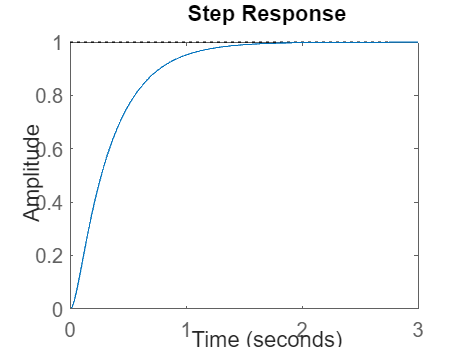

BCL2=[B1*Kr1;B1*Kr1];
CCL2=[Csalida -Dsalida*K1];
DCL2=[Dsalida*Kr1];
GCL2=ss(ACL2,BCL2,CCL2,DCL2);
step(GCL2)